Описание задачи

% lambda = -1; mu = -1.5;
% F= @(t,y,z) lambda*y+z(1,1);    G = @(t,y,z) mu*y+z(1,2);
% history = @(t,y) 1;
% delay = [1/2, 1/4];
% % z(i, j) - i это номер запаздывающей переменной,
% % j - номер коэф. запаздывания
% % sdde = @(t,y) F(t,y,z)dt + G(t,y,z)dW;
% 
% t_0 = 0;
% Yzero = 1;

Запаздывание в основной часте

% lambda = -1; mu = -1.5;
% F = @(t,y,z) lambda*y+z(1,1); 
% G = @(t,y,z) mu*y;
% history = @(t) [1; 1];
% delay = [1/2, 1/10];
% 
% t_0 = 0;
% Yzero = 1;

Запаздывание стохастической части

% lambda = -1; mu = -1.5;
% F = @(t,y,z) lambda*y; 
% G = @(t,y,z) mu*y+z(1,1);
% history = @(t) [1; 1];
% delay = [1/2, 1/10];
% 
% t_0 = 0;
% Yzero = 1;

Запаздывание в обеих частях

lambda = -1; mu = -1.5;
F = @(t,y,z) [lambda*y(2)+z(1,1); 1/lambda+y(1)+z(2,2)]; 
G = @(t,y,z) [mu*y(1)+z(1,2); 1/mu*y(2)+z(1,2)];
history = @(t) [1; 1];
delay = [1/2, 1/2];

t_0 = 0;
Yzero = [1; 1];

Начальные условия

rng("default");
h = 2^(-6);
rightBorder = 8;

Решение и построение графиков

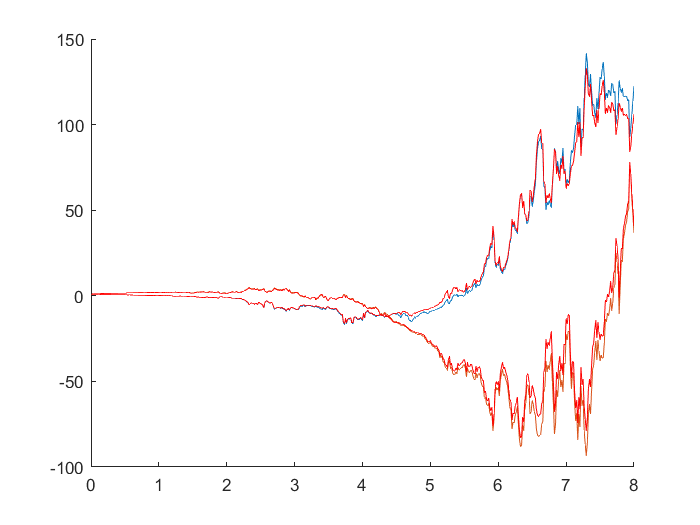

[T, Y] = EulerMaruyama_SDDE(F, G, h, t_0, Yzero, delay, history, rightBorder);
[Trock, Yrock] = ROCK_SDDE(F, G, h, t_0, Yzero, delay, history, rightBorder, 2, 0.2);
figure
hold on
plot (T, Y);
plot (Trock, Yrock, 'r')